% Q 3.2 
Xp = [1.5 3.5 5 6.9 8.4 10 11.2; 7 6.5 5 3.7 3 5 1.3]';
Xn = [1 2.1 3.1 4 5.9 7.9 9 10.5; 4.5 3.5 5.5 4.2 2.7 2.2 1.6 0.8]';

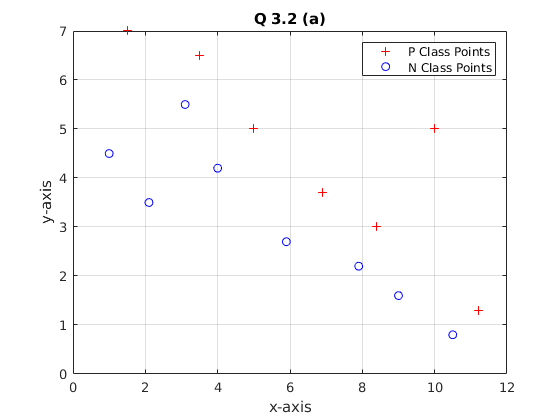

% a 
plot(Xp(:,1), Xp(:,2), '+r')
hold on; 
grid on; 
plot(Xn(:,1), Xn(:,2), 'ob')
legend('P Class Points', 'N Class Points')
xlabel('x-axis')
ylabel('y-axis')
title('Q 3.2 (a)')
hold off; 

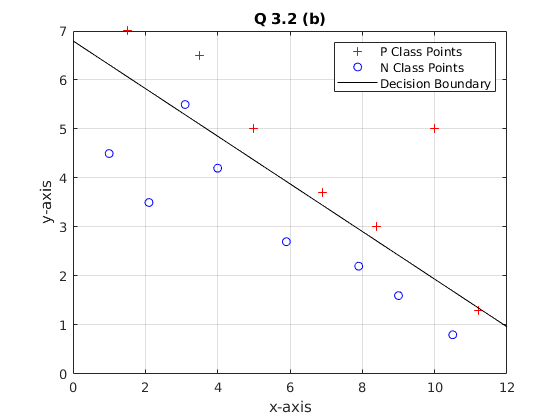

% b 
X = [Xp; Xn]';
X = [X ; ones(1,15)];
y = [ones(7,1); -1*ones(8,1)];

w_b = inv(X*X')*X*y;

x1_b = linspace(0, 12, 20);
x2_b = ((-w_b(1).*x1_b)-w_b(3))./w_b(2);

plot(Xp(:,1), Xp(:,2), '+r')
hold on; 
grid on; 
plot(Xn(:,1), Xn(:,2), 'ob')
plot(x1_b,x2_b, '-k')
legend('P Class Points', 'N Class Points', 'Decision Boundary')
xlabel('x-axis')
ylabel('y-axis')
title('Q 3.2 (b)')
hold off; 

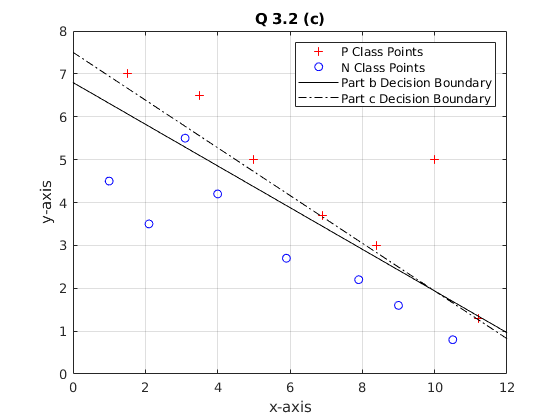

% c 
u = 3.2; 
P = 15; 
I = [1 0 0; 0 1 0; 0 0 0]; 

w_c = (inv((X*X')+u*P*I))*X*y; 

x1_c = linspace(0, 12, 20);
x2_c = ((-w_c(1).*x1_c)-w_c(3))./w_c(2);

plot(Xp(:,1), Xp(:,2), '+r')
hold on; 
grid on; 
plot(Xn(:,1), Xn(:,2), 'ob')
plot(x1_b,x2_b, '-k')
plot(x1_c,x2_c, '-.k')
legend('P Class Points', 'N Class Points', 'Part b Decision Boundary', 'Part c Decision Boundary')
xlabel('x-axis')
ylabel('y-axis')
title('Q 3.2 (c)')
hold off; 